# Transimpedance Amplifier Model - TSV620AILT

Purpose: The transimpedance amplifier serves to increase a small current input into a large voltage output. The transimpedance amplifier takes small currents from a photodiode, and converts it into a larger voltage which can be used for signal processing.

Standard Modelling Techniques: The transimpedance amplifier was modelled using SimScape blocks and subsystems. By creating a subsystem for the photodiode (VEMD2020X01), as well as the opamp (TSV620AILT), inputs such as wavelength and supply voltages can be passed in and an output voltage can be determined. Additionally, this model will help understand how different conditions affect the transimpedance amplifier.

Datasheet:

[https://www.mouser.ca/datasheet/2/389/tsv620-1852590.pdf](https://www.mouser.ca/datasheet/2/389/tsv620-1852590.pdf)

## Model:

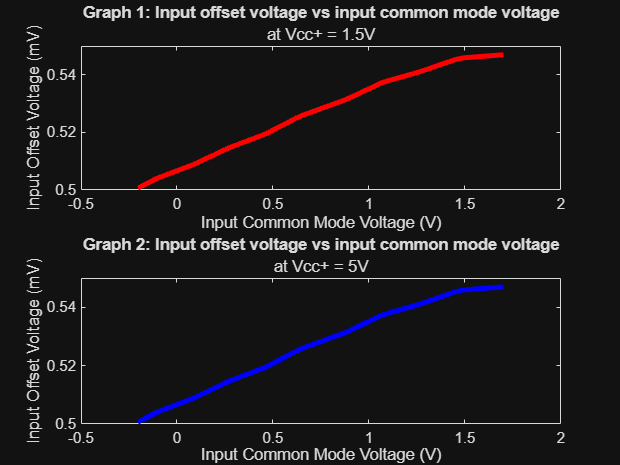

% Suppress all warnings
warning('off', 'all');

% Suppress specific algebraic loop warnings
warning('off', 'Simulink:Engine:AlgebraicLoop');

% Run the simulation and suppress command window output
evalc('sim_out = sim("C:\Users\timot\OneDrive\MATLAB\Components\Electrical\Models\Transimpedance Amplifier\transimpedance_amplifier_TSV620AILT.slx")');

% Extract data for the first graph
input_offset_voltage1 = sim_out.graph1.Data(:, 1);
input_common_mode_voltage1 = sim_out.graph1.Data(:, 2);

% Extract data for the second graph
input_offset_voltage2 = sim_out.graph2.Data(:, 1);
input_common_mode_voltage2 = sim_out.graph2.Data(:, 2);

% Create a figure window
figure;

% First subplot
subplot(2, 1, 1);
plot(input_common_mode_voltage1, input_offset_voltage1, 'r', 'LineWidth', 3); % Plot data
xlabel('Input Common Mode Voltage (V)'); % Set x-axis label
ylabel('Input Offset Voltage (mV)'); % Set y-axis label
title('Graph 1: Input offset voltage vs input common mode voltage', 'at Vcc+ = 1.5V'); % Set title
set(gca, 'OuterPosition', [0, 0.5, 1, 0.5]); % Adjust outer position [left, bottom, width, height]

% Second subplot
subplot(2, 1, 2);
plot(input_common_mode_voltage2, input_offset_voltage2, 'b', 'LineWidth', 3); % Plot data
xlabel('Input Common Mode Voltage (V)'); % Set x-axis label
ylabel('Input Offset Voltage (mV)'); % Set y-axis label
title('Graph 2: Input offset voltage vs input common mode voltage','at Vcc+ = 5V'); % Set title
set(gca, 'OuterPosition', [0, 0, 1, 0.5]); % Adjust outer position [left, bottom, width, height]